# 06 HO: Isoparametrix Elements - System

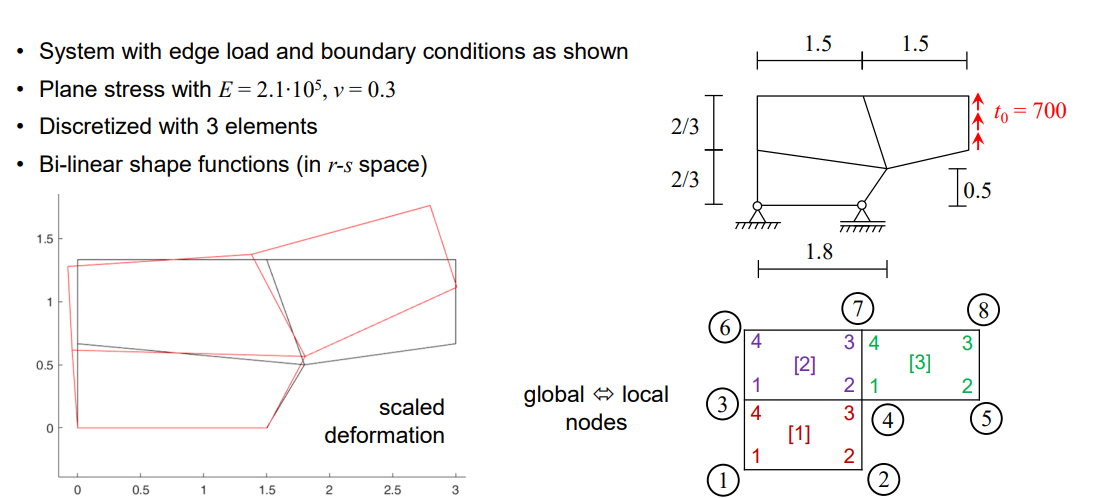

clear all; close all;

## Given parameters

E  = 2.1e5;
nu = 0.3;

C  = E / (1 - nu^2) * [1, nu, 0;
                      nu, 1, 0;
                      0,  0, (1 - nu) / 2];

## Model definition

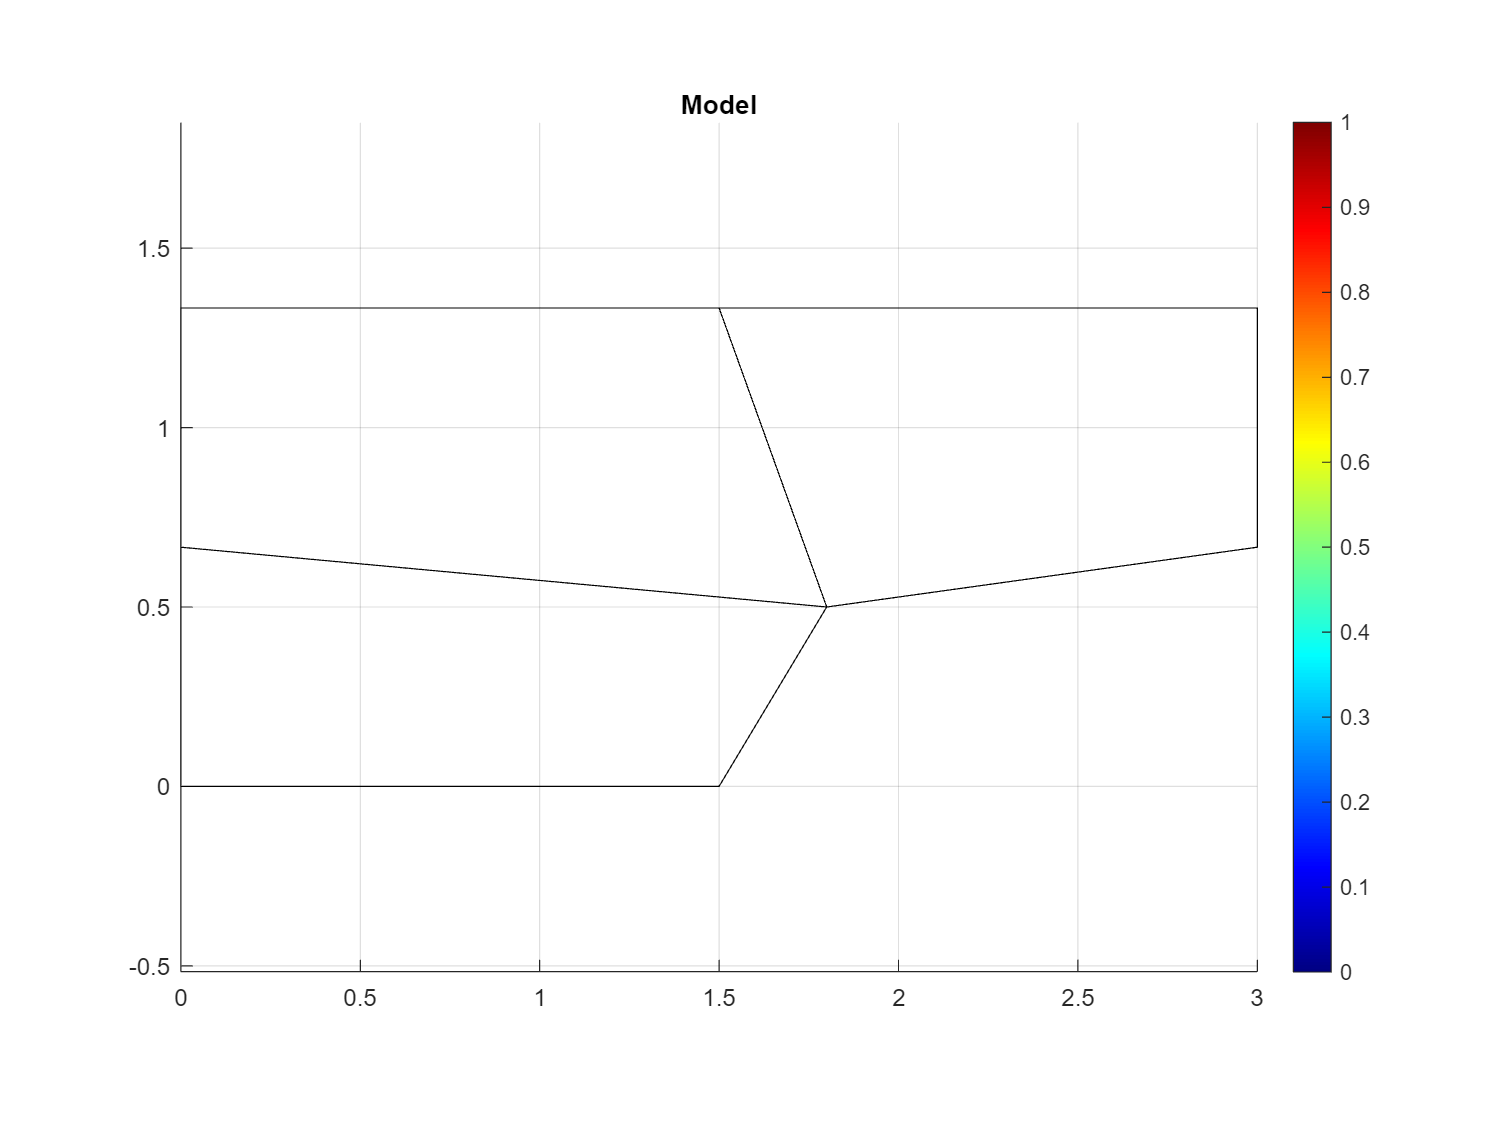

nodes = [0, 0;
         1.5, 0;
         0, 2/3;
         1.8, 0.5;
         3, 2/3;
         0, 4/3;
         1.5, 4/3;
         3, 4/3];

elements = [1 2 4 3;
            3 4 7 6;
            4 5 8 7];

plotElements(nodes, elements, 'Model'); grid on;

% Helper variables
nNodes = size(nodes, 1);
dofPerNode = 2;

nElements = size(elements, 1);
nodesPerElement = size(elements, 2);
dofPerElement = dofPerNode * nodesPerElement;
elementDOFs = globalElementDOFs(elements, 2);

## Generalized stiffness assembly

Set up system matrices

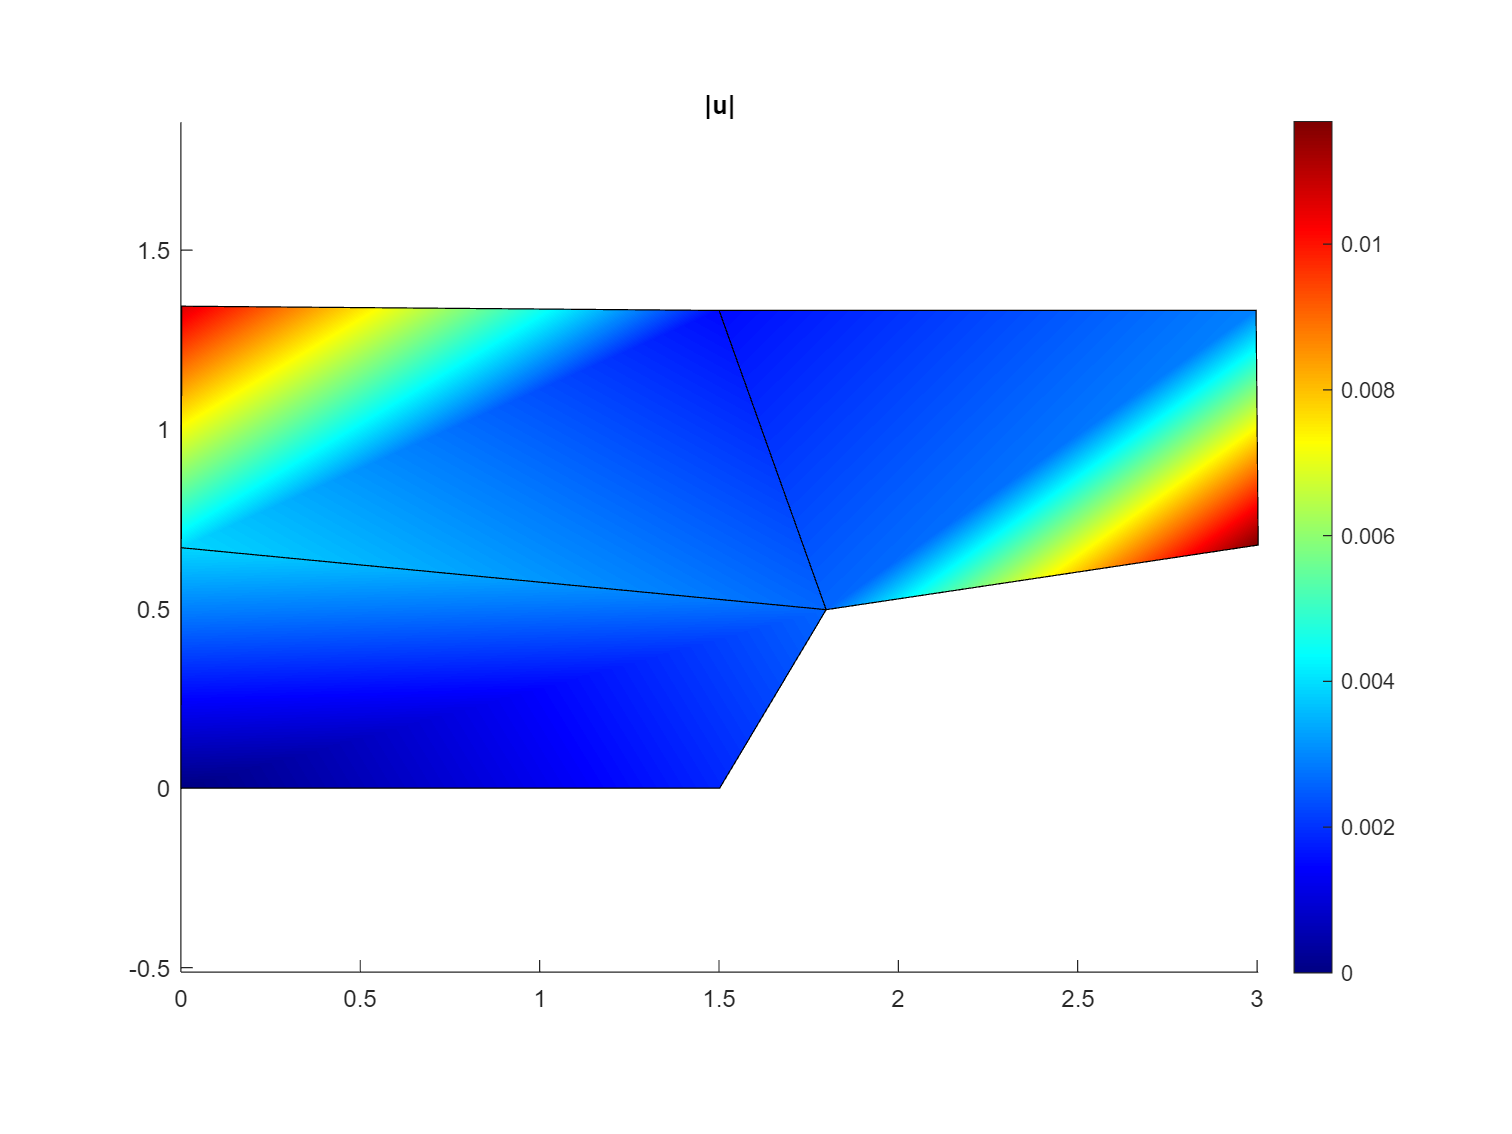

K = zeros(dofPerNode * nNodes);
u = zeros(dofPerNode * nNodes, 1);
f = zeros(dofPerNode * nNodes, 1);

% Set up stiffness matrix by looping over elements
integrationOrder = 2;
for e = 1 : nElements
    elementNodes = nodes(elements(e, :), :);
    KE = elementStiffness(C, elementNodes, integrationOrder);
    
    % Use element connectivity to add element stiffness to global stiffness matrix
    K(elementDOFs(e, :), elementDOFs(e, :)) =   K(elementDOFs(e, :), elementDOFs(e, :)) + ...
                                                KE; 
end

% Load
f([10, 16]) = 1 / 2 * 700 * 2 / 3;

% Solve system
fixeddofs = [1, 2, 4];
freedofs = setdiff(1 : nNodes * dofPerNode, fixeddofs);

u(freedofs) = K(freedofs, freedofs) \ f(freedofs);

% Plot displacement as x0 + u
scale = 1;
uNodes = transpose(reshape(u, dofPerNode, nNodes));
uMagnitude = vecnorm(uNodes, 2, 2);
plotElements(nodes + scale * uNodes, elements, '|u|', uMagnitude);

## Postprocessing: Stress

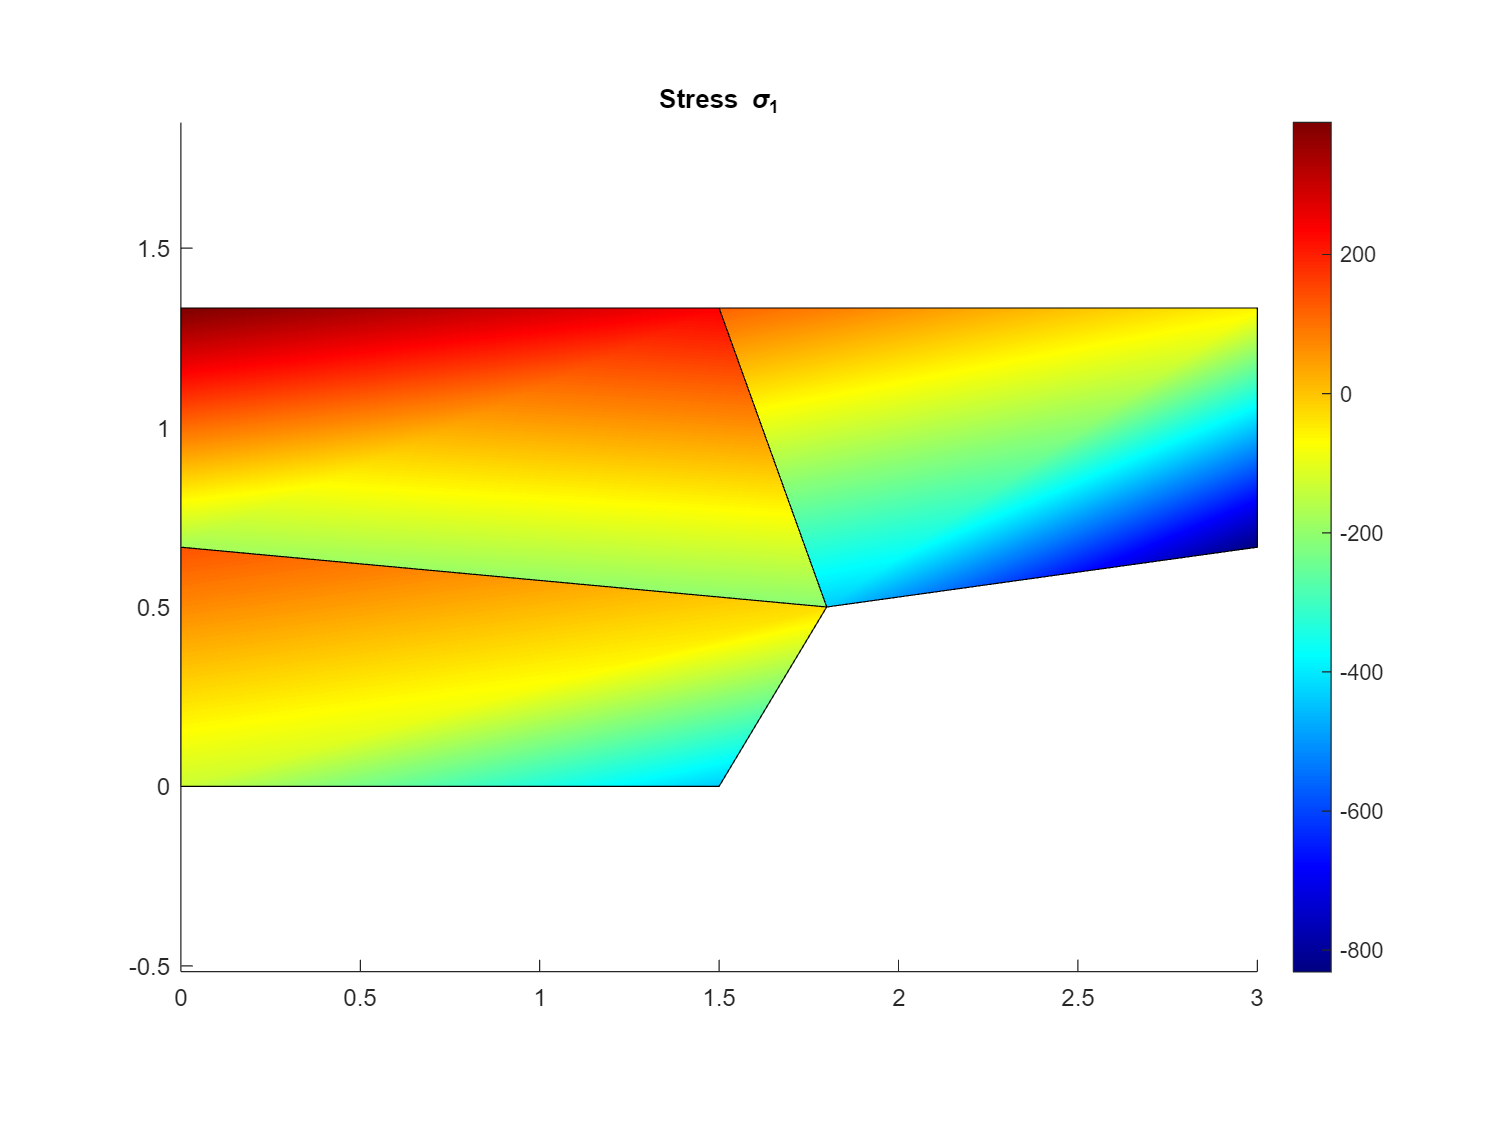

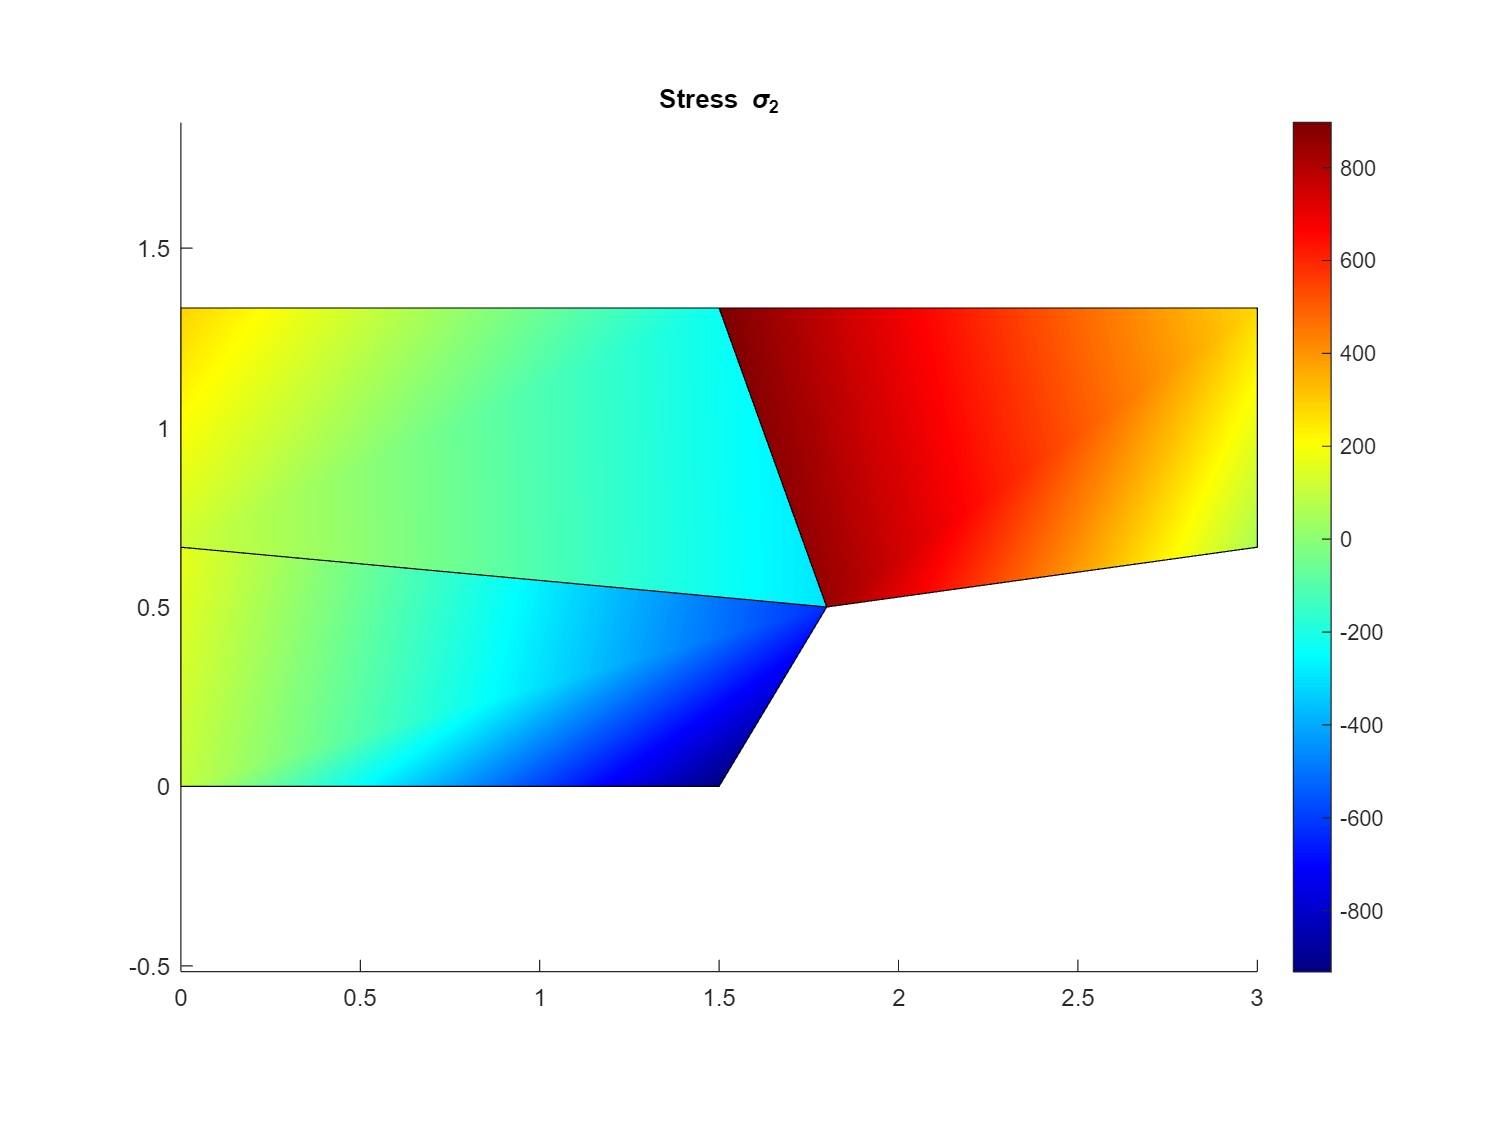

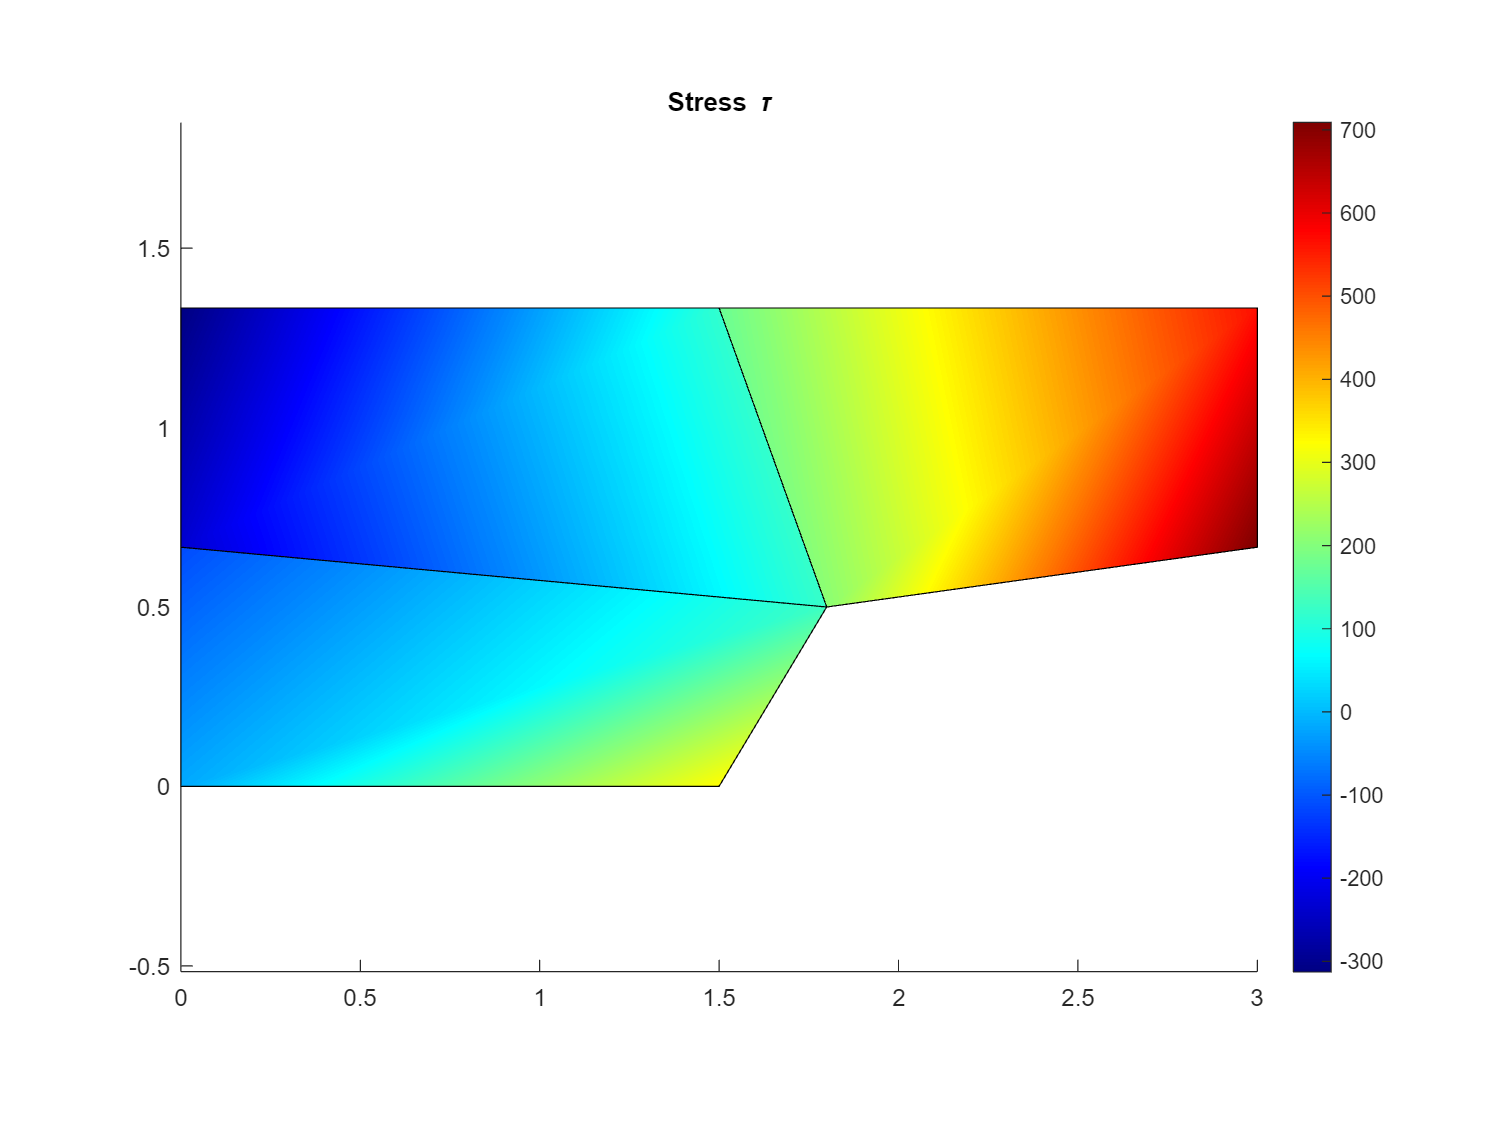

patchesSigma1 = plotElements(nodes, elements, 'Stress \sigma_1');
patchesSigma2 = plotElements(nodes, elements, 'Stress \sigma_2');
patchesSigma12 = plotElements(nodes, elements, 'Stress \tau');

% Initialize cells or arrays for stress
stressGauss     = cell(nElements, 1);
stressNodes     = cell(nElements, 1);
stressNodesExp  = cell(nElements, 1);
stressCenter    = zeros(nElements, 3);

% Element-wise stress calculation
[gauss_rs, wg] = gaussianPoints2D(2);
for e = 1 : nElements
    elementNodes = nodes(elements(e, :), :);
    
    
    
    % ==================================================
    % Compute stress at GAUSS POINTS
    % ==================================================
    stressGauss{e} = zeros(4, 3);
    for g = 1 : size(gauss_rs, 1)
        % Compute jacobian for element at GAUSS POINT
        [~, dh] = linearShapeFunctions(gauss_rs(g, 1), ...
                                       gauss_rs(g, 2));
        J = dh * elementNodes;
        dhdx = J \ dh;
        B = bMatrix(dhdx);

        % Evaluate stress at GAUSS POINT
        stressGauss{e}(g, :) = C * B * u(elementDOFs(e, :));
    end
    
    
    
    % ==================================================
    % Compute stress at NODES 
    % ==================================================
    stressNodes{e} = zeros(4, 3);
    elementNodesNatural = [-1, -1; 
                            1, -1; 
                            1, 1; 
                           -1, 1];
    for n = 1 : size(elementNodesNatural, 1)
        % Compute jacobian for element at NODE
        [~, dh] = linearShapeFunctions(elementNodesNatural(n, 1), ...
                                       elementNodesNatural(n, 2));
        J = dh * elementNodes;
        dhdx = J \ dh;
        B = bMatrix(dhdx);

       % Evaluate stress at NODES
        stressNodes{e}(n, :) = C * B * u(elementDOFs(e, :));
    end
    
    
    
    % ==================================================
    % EXTRAPOLATE integration point stress to NODES
    % ==================================================
    elementNodesExtrapolation = sqrt(3) * [-1, -1; 
                                            1, -1; 
                                            1,  1; 
                                           -1,  1];
    h = linearShapeFunctions(   elementNodesExtrapolation(:, 1), ...
                                elementNodesExtrapolation(:, 2));
    stressNodesExp{e} = h * stressGauss{e};

    % Compute stress in element center
    [~, dh] = linearShapeFunctions(0, 0);
    J = dh * elementNodes;
    stressCenter(e, :) = C * bMatrix(dhdx) * u(elementDOFs(e, :));

    % Plot stress by interpolating nodal values
    patchesSigma1(e).set('FaceColor', 'interp', 'FaceVertexCData', stressNodesExp{e}(:, 1));
    patchesSigma1(e).FaceAlpha = 1;
    patchesSigma2(e).set('FaceColor', 'interp', 'FaceVertexCData', stressNodesExp{e}(:, 2));
    patchesSigma2(e).FaceAlpha = 1;
    patchesSigma12(e).set('FaceColor', 'interp', 'FaceVertexCData', stressNodesExp{e}(:, 3));
    patchesSigma12(e).FaceAlpha = 1;
end

## Additional functions

function elementDOFs = globalElementDOFs(elements, dim)
    % Return global DOFs for elements
    % INPUT
    %   elements (array)    nodes per element as (nElements x nodesPerElement) array
    %   dim (scalar)        dimension
    % OUTPUT
    %   elementDOFs (array) global DOFs per element as (nElements x (dim * nodesPerElement)) array

    switch dim
        case 1
            elementDOFs = elements;
        case 2
            nodes       = reshape(elements', numel(elements), 1);
            elementDOFs = [2 * nodes - 1, 
                           2 * nodes]';
            elementDOFs = transpose(reshape(elementDOFs(:), 2 * size(elements, 2), size(elements, 1)));
        otherwise
            error("not implemented");
    end
end

function KE = elementStiffness(C, elementNodes, integrationOrder)
    % Compute element stiffness matrix
    % INPUT
    %   C (array)                   Constitutive matrix
    %   nodes (array)               Nodes for element
    %   integrationOrder (scalar)   Integration order for gauss quadrature
    % OUTPUT
    %   KE (array)                  Element stiffness matrix

    % Prepare element stiffness matrix for mechanical analysis
    KE = zeros(size(elementNodes, 1) * size(elementNodes, 2));

    [xg, wg] = gaussianPoints2D(integrationOrder);              % STEP1: GAUSS POINTS

    % Integrate stiffness
    for g = 1 : size(xg, 1)
        [~, dh] = linearShapeFunctions( xg(g, 1), ...           % STEP2: DERIVATIVES OF SHAPE FUNCTIONS w.r.t. r,s,t
                                        xg(g, 2));              
        J = dh * elementNodes;                                  % STEP3: JACOBIAN

        dhdx = J \ dh; % inv(J) * dh;
        B = bMatrix(dhdx);                                      % STEP4: DERIVATIVES OF SHAPE FUNCTIONS w.r.t. x,y,z -> B matrix

        KE = KE + wg(g) * B' * C * B * abs(det(J));             % STEP5: STIFFNESS MATRIX
    end
end

% Shape functions
function [h, dh] = linearShapeFunctions(r, s)
    % Evaluate shape functions for linear quadrilateral element
    % INPUT
    %   r (array)   r coordinate for evaluation of shape functions and derivatives in natural coordinates
    %   s (array)   s coordinate for evaluation of shape functions and derivatives in natural coordinates
    % OUTPUT
    %   h (array)           Shape functions at (r, s), row per given point
    %   dh (array)          Derivatives of shape functions at first (r, s)

    h1 = 1/4 * (1 - r) .* (1 - s);
    h2 = 1/4 * (1 + r) .* (1 - s);
    h3 = 1/4 * (1 + r) .* (1 + s);
    h4 = 1/4 * (1 - r) .* (1 + s);

    dh1dr = -1/4 * (1 - s);
    dh1ds = -1/4 * (1 - r);
    dh2dr = 1/4 * (1 - s);
    dh2ds = -1/4 * (1 + r);
    dh3dr = 1/4 * (1 + s);
    dh3ds = 1/4 * (1 + r);
    dh4dr = -1/4 * (1 + s);
    dh4ds = 1/4 * (1 - r);

    h = [h1, h2, h3, h4];
    dh = [dh1dr, dh1ds;
          dh2dr, dh2ds;
          dh3dr, dh3ds;
          dh4dr, dh4ds]';
end

% H and B matrices
function H = hMatrix(r, s)
    % Evaluate H matrix for linear quadrilaterial element
    % INPUT
    %   r (array)   r coordinate for for evaluation of shape functions and derivatives in natural coordinates
    %   s (array)   s coordinate for for evaluation of shape functions and derivatives in natural coordinates
    % OUTPUT
    %   H (array)   B matrix for linear quadrilateral element in natural coordinates

    h = linearShapeFunctions(r, s);
    H = [h(1), 0, h(2), 0, h(3), 0, h(4), 0;
         0, h(1), 0, h(2), 0, h(3), 0, h(4)];
end

function B = bMatrix(dhdx)
    % Evaluate B matrix for linear quadrilaterial element
    % INPUT
    %   r (array)   r coordinate for for evaluation of shape functions and derivatives in natural coordinates
    %   s (array)   s coordinate for for evaluation of shape functions and derivatives in natural coordinates
    % OUTPUT
    %   B (array)   B matrix for linear quadrilateral element in natural coordinates

    % Initialize B matrix
    B = zeros(3, 8);

    % Define linear indices for first B matrix -> B1 corresponding to node 1
    indicesBi = [1; 5; 3; 6];
    indicesdHi = [1; 2; 2; 1];

    % Repeat indices for node 2 to node 4
    indicesB = indicesBi + (0 : 6 : 6 * 4 - 6);
    indicesdH = indicesdHi + (0 : 2 : 4 * 2 - 2);

    % Assign dh entries to B matrix
    B(indicesB) = dhdx(indicesdH);
end

% Plot functions
function p = plotElements(nodes, elements, title, color)
    % Plot elements by plotting a patch for each element
    % INPUT
    %   nodes (array)       Nodal coordinates as (nNodes x 2) array
    %   elements (array)    Nodal indices per element as (nElements x 4) array
    %   color (array)       OPTIONAL: Color for nodes or elements per row
    % OUTPUT
    %   p (array)           Patches for elements

    newFigure(title);
    hold on;
    for e = 1 : size(elements, 1)
        elementNodes = nodes(elements(e, :), :);
        p(e) = patch(elementNodes(:, 1), elementNodes(:, 2), 'w');
        if nargin > 3
            if size(color, 1) == size(nodes, 1)
                % Interpolate between nodal values
                p(e).set('FaceColor', 'interp', 'FaceVertexCData', color(elements(e, :)));
            elseif size(color, 1) == size(elements, 1)
                % Color per element
                p(e).set('FaceColor', 'flat', 'FaceVertexCData', color(e));
            end
            clim([min(color), max(color)]);
            % p(e).EdgeAlpha = 0;
        else
            p(e).FaceAlpha = 0;
        end
    end
    hold off;
end

function f = newFigure(figureTitle)
    % Open figure and set several common options
    % INPUT
    %   figureTitle (string/char array)     OPTIONAL: title for figure
    % OUTPUT
    %   f (figure) 

    f = figure;
    f.Position([3, 4]) = 1.5 * f.Position([3, 4]);
    f.Position(2) = f.Position(2) - f.Position(4)/3;
    axis equal; 
    colormap jet;
    colorbar;
    if nargin > 0
        title(figureTitle);
    end
end